# Tucci Lorenzo (0001190439) LEDS Assignment

clear all
close all
addpath ./Functions;

## **1) Estimation**

Data collection:

N=6000;
Student = 'Tucci Lorenzo';
Matriculation = '0001190439';
[Measurements] = IdentifyThis(N,Student,Matriculation);
u=Measurements.u;
y=Measurements.y;

Since the input u is a vector of all zeroes, I have an AR model. I divide the data set into training and validation set: 65% of data for the training set and 35% of data for the validation set.

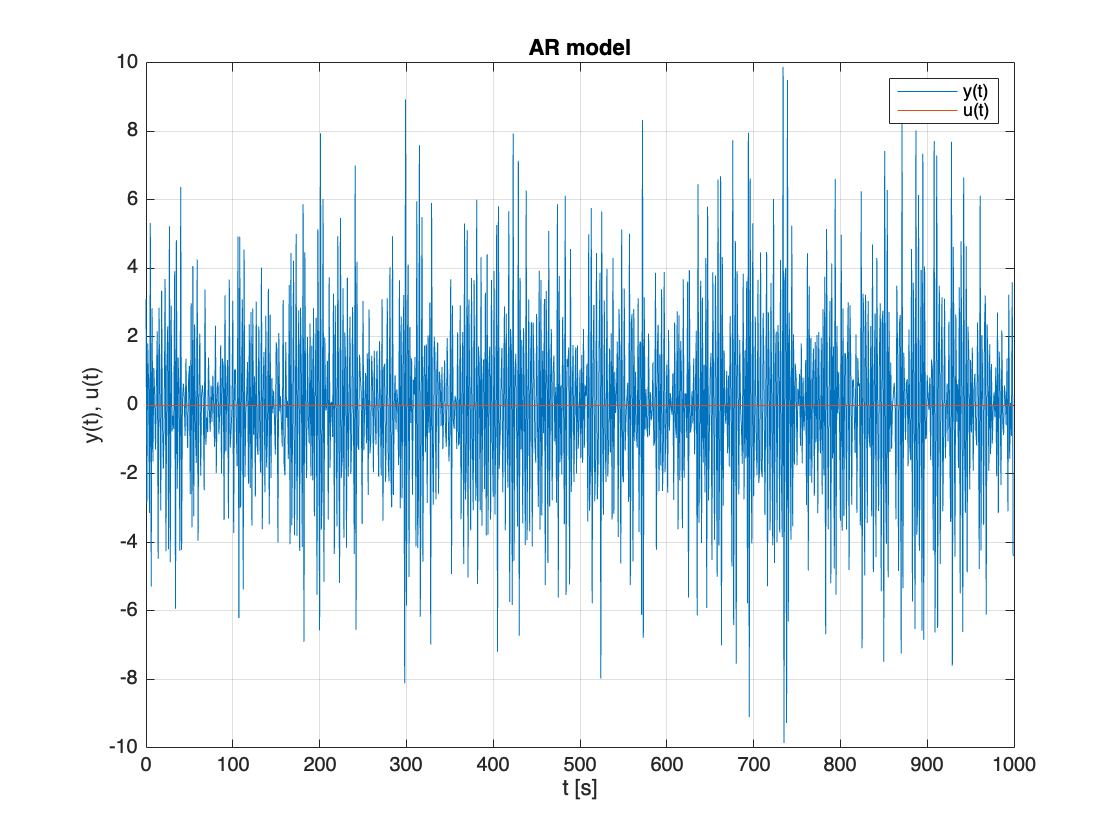

time = [0:1:N-1];
y_train = y(1:0.65*N); % defining the training set
y_valid = y(0.65*N : end); % defining the validation set

figure();
plot(time(1:1000),y(1:1000));
grid on;
xlabel("t [s]");
ylabel("y(t), u(t)");
title("AR model");
hold on;
plot(time(1:1000),u(1:1000));
legend('y(t)', 'u(t)');

I'll plot the output autocorrelations up to delay 10. We can notice that the autocorrelation function of the output goes to zero,

 as we expect if the system is stable.

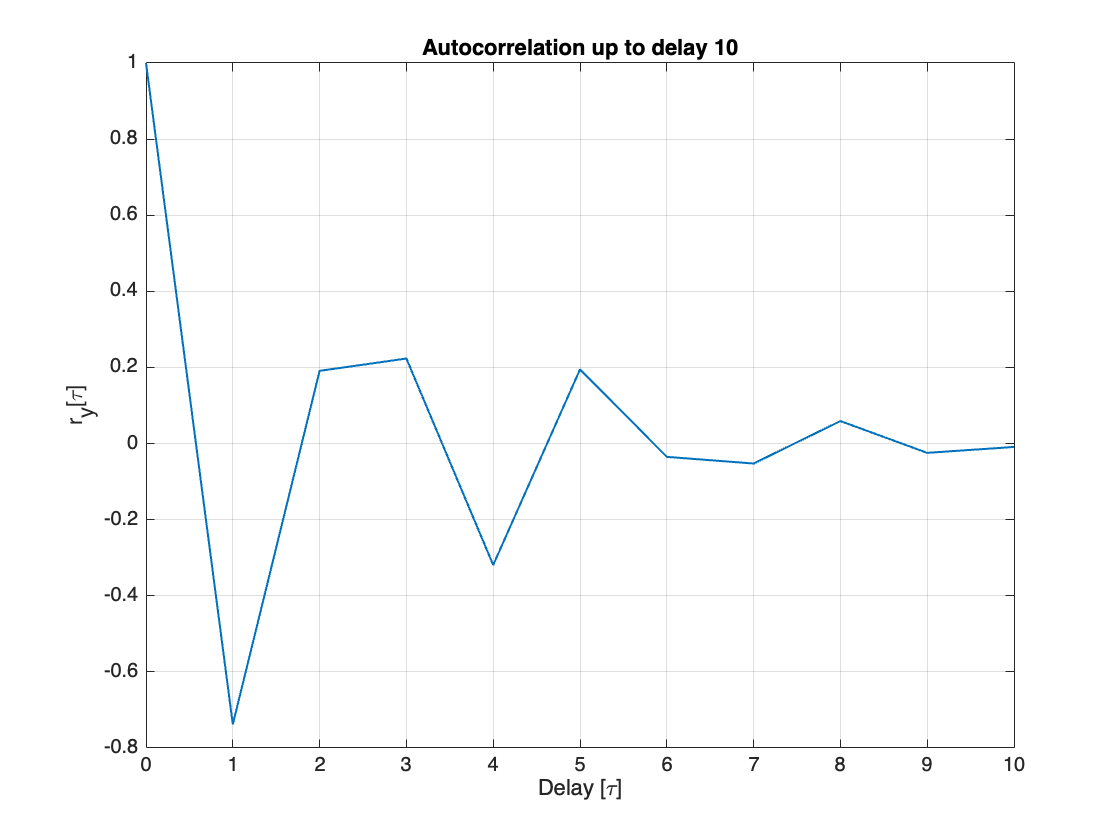

max_lag = 10;
[autocorr_samples, lags] = autocorr(y,max_lag); % autocorr() is a function used to compute the autocorrelation from econometrics toolbox

% plot of autocorrelation
figure();
ax = plot(lags(1:max_lag+1),autocorr_samples(1:max_lag+1),"LineWidth",1);
grid on;
xlabel("Delay [\tau]");
ylabel("r_y[\tau]");
title("Autocorrelation up to delay 10");

Starting from our linear regression form:


$$y\left(t\right)=\varphi^T \theta +e\left(t\right)$$
 

that in matrix form is: $Y=-H_y \left(n\right)\theta +\varepsilon$ ,  we are going to find the batch estimator $\hat{\theta}$.

Such estimator is chosen because is the one that minimizes the loss function $J\left(\theta \right)={\left\|Y-H\theta \right\|}^2$ and it's equal to 

$\widehat{\theta} ={\left(H^T H\right)}^{-1} H^T Y$.

Since the batch algorithm is inefficient for a large number of samples, due to the fact that every time we get a new data sample we must recompute the Hankel matrix, we use a recursive algorithm ( as requested in the point 2).

The estimation algorithm that I'm going to use is the Recursive Least Squares II that doesn't use the matrix inversion lemma. 

Starting from a batch estimate of theta computed with the function AR_LS that consider the first N_batch data samples; we apply the RLS II to the training set using the function AR_RLS and at the end we find the cost function on the validation set using cost_function_J.

Meanwhile, doing that, we are also finding the model complexity p, that corresponds to the minimum value of the cost function. The estimation of p is done inside the for cicle and then is plotted.

Limit_n = 30;
Jv = zeros(Limit_n,1);
for p=1:Limit_n
    N_batch = p*4;                                            % N_batch chosen accordingly to the model complexity increase
    theta = AR_RLS(y_train,p,N_batch);                        % Estimation on training set
    Jv(p) = cost_function_J(y_valid,theta);                   % Computation of J
end

[value,n_minJ]=min(Jv);                                       % Finding n for lowest J
disp('min J and equivalent p');

min J and equivalent p


disp([value, n_minJ]);

    1.0574    6.0000



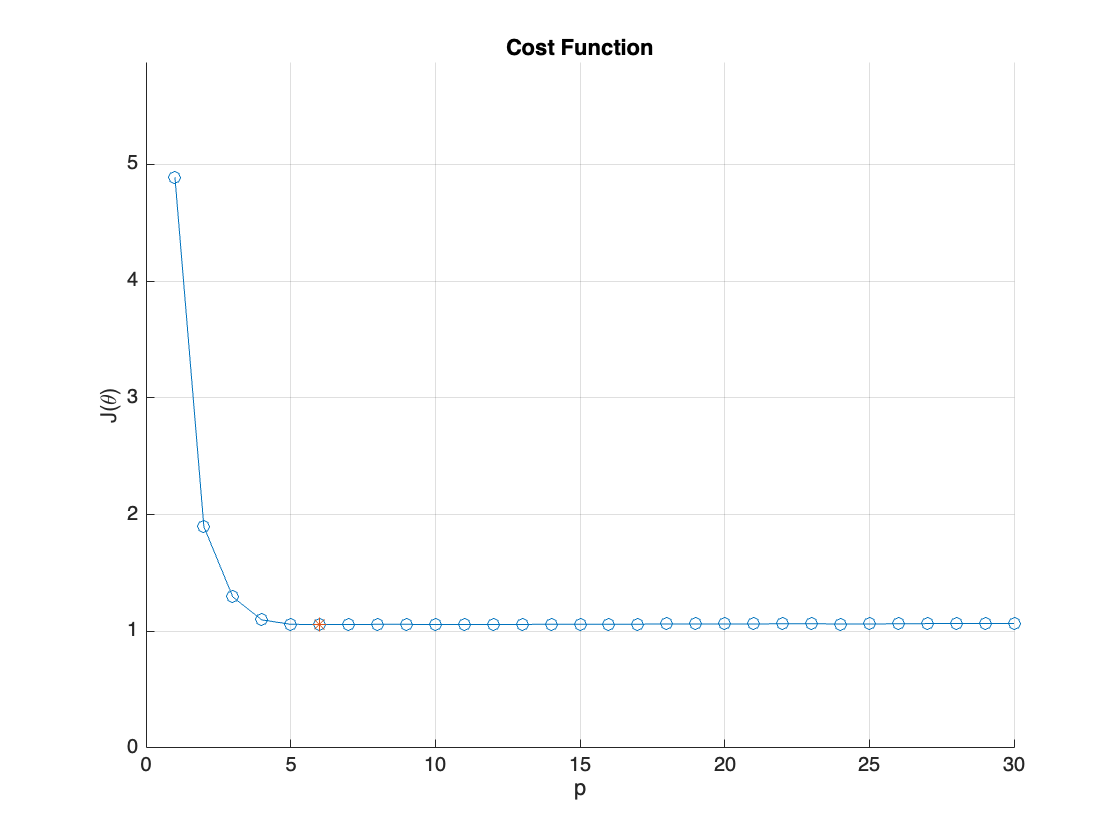


figure();                                                     % Plotting the behaviour of J
hold on
plot(Jv,'-o');
plot(n_minJ,Jv(n_minJ),'*');
grid on;
ylabel('J(\theta)');
xlabel('p');
ylim([0 max(Jv)*1.2]);
title('Cost Function');

Another criterion used to obtain the model complexity is Akaike Information Criterion (AIC) that introduces a penalization of 

the loss function with increasing orders and is defined as:


$$\textrm{AIC}=\textrm{Nlog}\left(J\left({\hat{\theta} }_N \right)\right)+2p$$


At the end the AIC is plotted.

Aic = zeros(Limit_n,1);
for p=1:Limit_n
    N_batch = p*4;
    theta = AR_RLS(y_train,p,N_batch);                           % Estimation of parameters
    Aic(p) = AIC_function(y_valid,theta);                        % Compute AIC
end

[AIC_min, p_AIC] = min(Aic);                                     % Finding p for lowest AIC
disp('min AIC and equivalent p');

min AIC and equivalent p


disp([AIC_min, p_AIC]);

  129.0257    6.0000



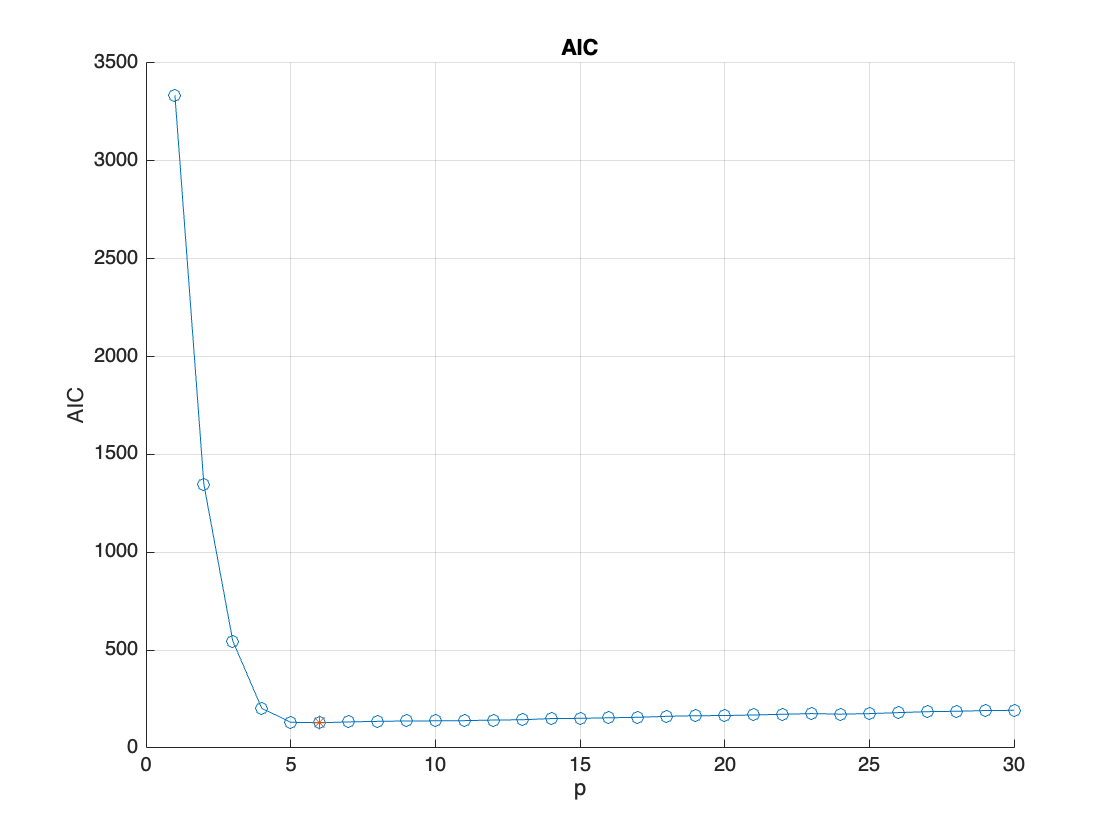


figure();
hold on
plot(Aic,'-o');
plot(p_AIC,Aic(p_AIC),'*');
grid on;
ylabel('AIC');
xlabel('p');
title('AIC');

Choosing the model complexity p = 6, according to AIC, I'll compute the final theta estimate.

p = 6;
N_batch = p*4;
final_theta = AR_RLS(y,p,N_batch);
disp('Final theta is:');

Final theta is:


disp(final_theta);

    2.0349
    2.3480
    1.6923
    0.8664
    0.2882
    0.0569



In order to validate the model we use the Whiteness Test:  it must check the behaviour of the residuals obtained with such model with respect to the samples. In particular, $\varepsilon \left(t,{\hat{\theta} }_N \right)$ should behave as a white noise.

So it's a binary test

 
$$\left\lbrace \begin{array}{ll}
H_0 : & \varepsilon \left(t,\hat{\theta_N } \right)\;\textrm{is}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process}\\
H_1 : & \textrm{not}\;{\;H}_0 
\end{array}\right.$$


The other test that can be used to validate the model is the Test of Cross-correlation, that checks the uncorrelationess between the residuals and the input signal; but since in AR models case $u\left(t\right)=0,\forall t$ applying this test is not possible.

H = -AR_Hankel(y,p);

eps = y(p+1:end)-H*final_theta;                         % Computing the residuals

m = 80;                                                 % number of sample autocorrelationsof the residuals that is also the number of gaussian tests that will be performed
alpha = 0.05;                                           
N = N-p;
r = autocorr(eps,m);                                    % It gives normalized quantities
m_= 0;
for i=2:m+1
    if abs(r(i)) > 1.96/sqrt(N)
        m_ = m_+1;                                      % number of failed tests
    end
end

% to make the final decision I use the Anderson test
if m_/m <= alpha
    fprintf('Accept H0: model is accepted');
else
    fprintf('Reject H0: model is rejected');
end

Accept H0: model is accepted

I plot also the autocorrelation

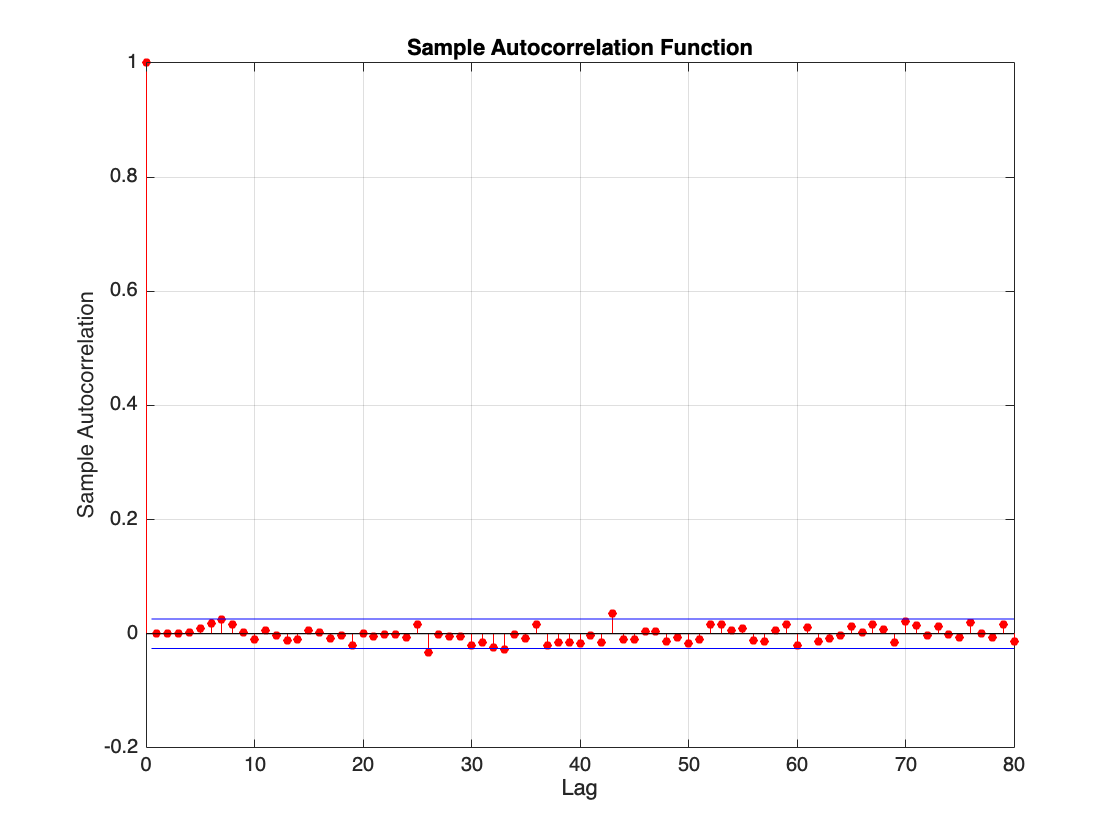

figure();
autocorr(eps,m);

## **2) Classification**

Data collection:

N=3000;
Student = 'Tucci Lorenzo';
Matriculation = '0001190439';
[FeatureSet] = ClassifyThose(N,Student,Matriculation);

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Plotting the data we see that we have two inputs and three classes.

The plot is composed by the values of Utrain corresponding to the three classes. 

Looking at it, we notice that is the case of a multiclass problem and the three regions can be divided by using linear decision boundaries.

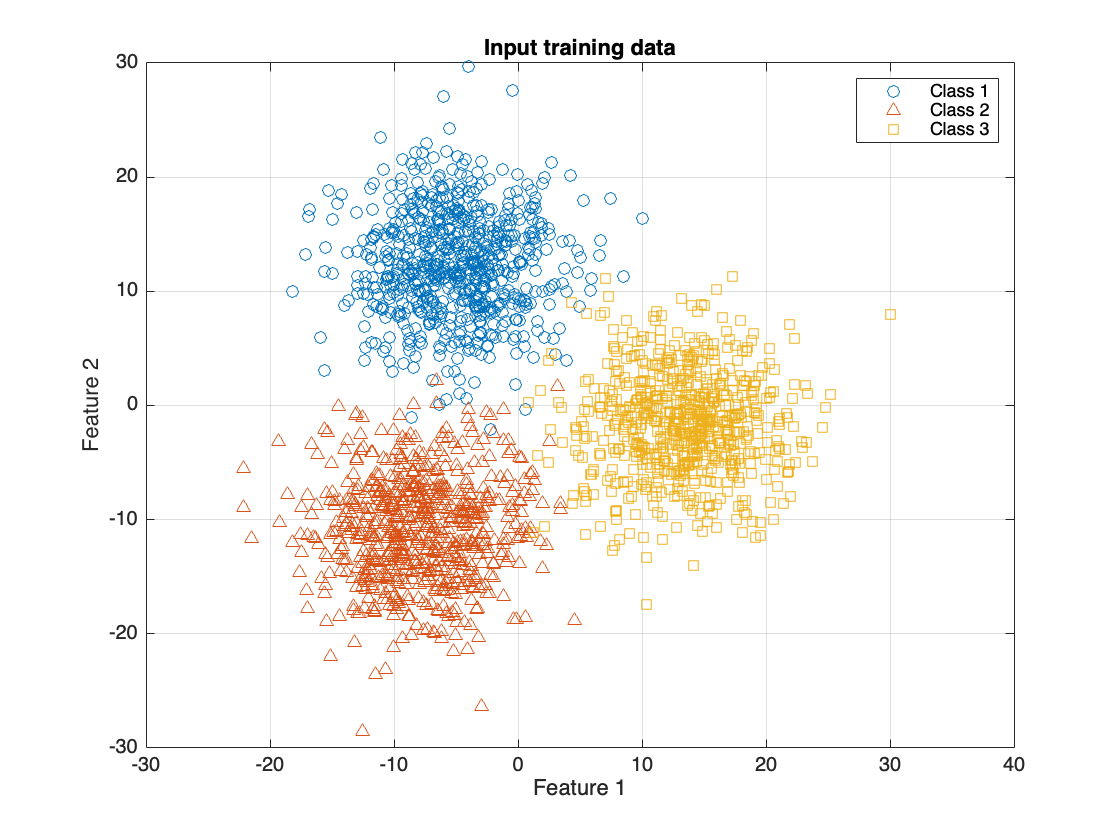

figure();
plot(Utrain(Ytrain==1,1),Utrain(Ytrain==1,2),"o"); 
hold on
grid on
plot(Utrain(Ytrain ==2,1),Utrain(Ytrain==2,2),"^");
hold on
grid on
plot(Utrain(Ytrain==3,1),Utrain(Ytrain==3,2),"s");

xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1','Class 2','Class 3');
title('Input training data');

Now I plot the test data as well.

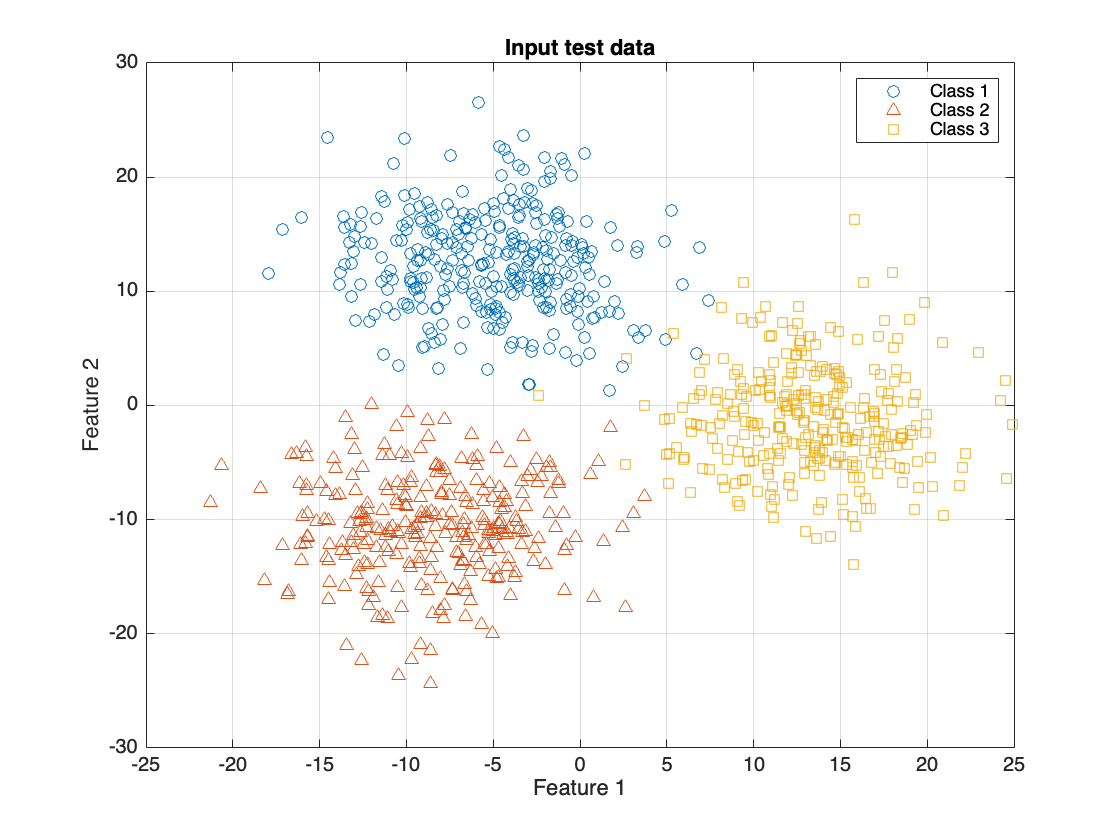

figure();
plot(Utest(Ytest==1,1),Utest(Ytest==1,2),"o");
hold on
grid on
plot(Utest(Ytest ==2,1),Utest(Ytest==2,2),"^");
hold on
grid on
plot(Utest(Ytest==3,1),Utest(Ytest==3,2),"s");

xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1','Class 2','Class 3');
title('Input test data');

In order to find a classifier for the feature set, the approach chosen is to use a probabilistic model. In particular, I use Logistic regression to approximate a Bayes classifier. Since it is a multi-class problem, I use the Softmax function.

To find the parameter vector theta I use the Newton Raphson Algorithm that is implemented by using the function NewtRaphAlg(), where, as suggested, the first estimate of theta is taken as all zeros vector.

phi = [ones(size(Utrain,1),1), Utrain];                             % computing the phi vector adding the bias
step_size = 0.3;                                                    % step size eta
delta = 1e-3;                                                       % delta for stopping criterion
theta_estimate = NewtRaphAlg(phi, Utrain, step_size, delta,Ytrain); % computing the theta by using the algorithm
disp('Theta hat is:');      

Theta hat is:


disp(theta_estimate);

    2.5611
    0.0981
   -0.0723



% assigning boolean values to Y_i when an element of Ytrain is equal to i
Y_1 = (Ytrain == 1);                                    
Y_2 = (Ytrain == 2);
Y_3 = (Ytrain == 3);
% computing the final theta that has dimension 3x3, evaluating the Utrain
% data wrt each Y_i
theta_1 = NewtRaphAlg(phi, Utrain, step_size, delta,Y_1);
theta_2 = NewtRaphAlg(phi, Utrain, step_size, delta,Y_2);
theta_3 = NewtRaphAlg(phi, Utrain, step_size, delta,Y_3);
theta_tot = [theta_1, theta_2, theta_3];

disp('The final theta is:');

The final theta is:


disp(theta_tot);

   -0.2828   -0.2808   -0.2930
   -0.0279   -0.0423    0.0702
    0.0636   -0.0550   -0.0086




% applying the Softmax

Yf= zeros(length(Utrain) ,1); %vector to collect values of the estimate of the output computed with the softmax function
for i = 1:size(Utrain, 1)
    u_i = Utrain(i, :);  
    y_i = ClassifSoftmax(u_i, theta_tot); 
    Yf(i)= y_i;
end

Now I'm going to plot the linear decision boundaries and then the misclassified data.

% plotting again Utrain data
figure();
plot(Utrain(Ytrain==1,1),Utrain(Ytrain==1,2),"o");
xlabel("u_1");
ylabel("u_2");
hold on
grid on
plot(Utrain(Ytrain ==2,1),Utrain(Ytrain==2,2),"^");
hold on
grid on
plot(Utrain(Ytrain==3,1),Utrain(Ytrain==3,2),"s");

xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1','Class 2','Class 3');

% Defining the grid to plot the boundaries
xrange = linspace(min(Utrain(:,1)), max(Utrain(:,1)), 100);
yrange = linspace(min(Utrain(:,2)), max(Utrain(:,2)), 100);
[X1, X2] = meshgrid(xrange, yrange);

% Computing the boundaries between pairs of classes (hyperplanes)
phi_grid = [ones(numel(X1),1), X1(:), X2(:)];

% Boundary between class 1 and 2
Z12 = phi_grid * (theta_tot(:,1) - theta_tot(:,2));
Z12 = reshape(Z12, size(X1));
contour(X1, X2, Z12, [0 0], 'y--', 'LineWidth', 1, 'DisplayName', 'Boundary 1'); 

% Boundary between class 1 and 3
Z13 = phi_grid * (theta_tot(:,1) - theta_tot(:,3));
Z13 = reshape(Z13, size(X1));
contour(X1, X2, Z13, [0 0], 'r--', 'LineWidth', 1, 'DisplayName', 'Boundary 2'); 

% Boundary between class 2 and 3
Z23 = phi_grid * (theta_tot(:,2) - theta_tot(:,3));
Z23 = reshape(Z23, size(X1));
contour(X1, X2, Z23, [0 0], 'b--', 'LineWidth', 1, 'DisplayName', 'Boundary 3'); 
title('Training set class boundaries (Softmax)');


Now I compute the misclassified data on the training set.

mismatches_train = (Yf ~= Ytrain) ; % boolean equal to 1 for every mismatch
count_mis_train=0;
for i=1:length(mismatches_train)
  if mismatches_train(i)==1
       count_mis_train= count_mis_train +1;
  end
end
% Compute error rate on Training set

N_Train = length(Ytrain);             
Er_Train=count_mis_train/N_Train;
disp('The error rate on the training set is:');

The error rate on the training set is:


Er_Train

Er_Train = 0.0086

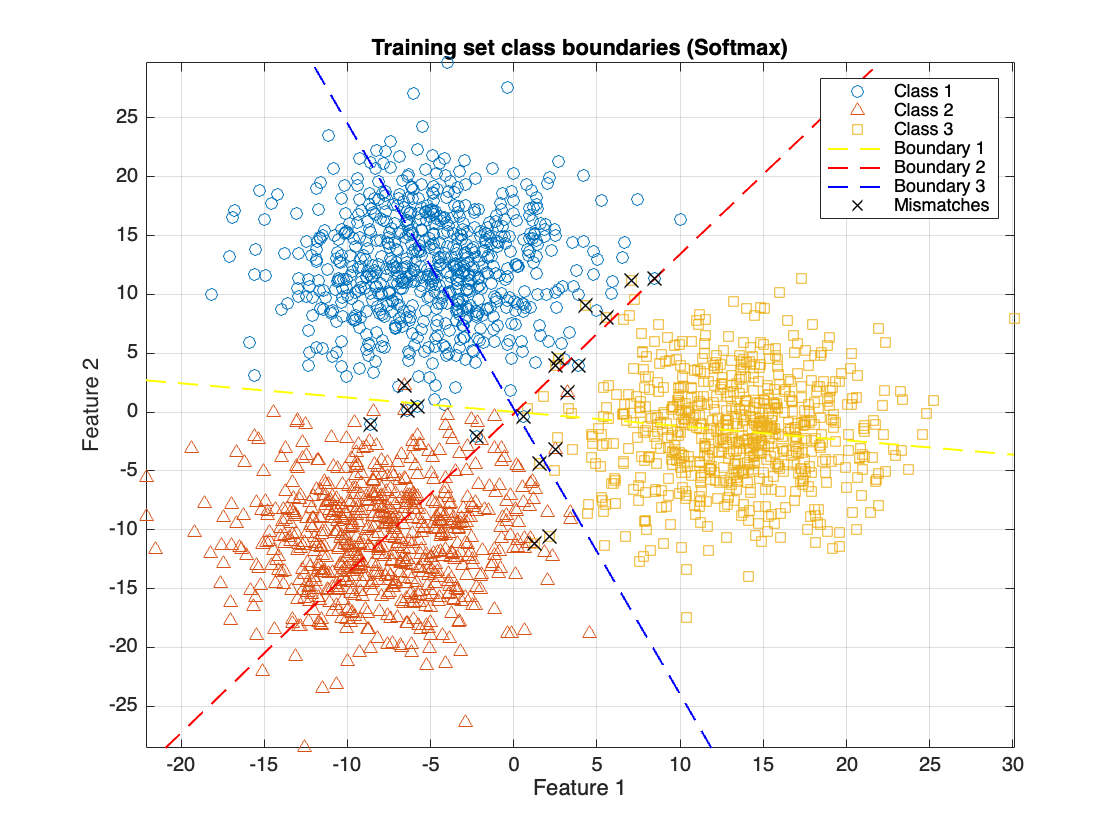

% plotting the mismatches
scatter(Utrain(mismatches_train == 1,1), Utrain(mismatches_train==1,2),80, 'k', 'x','LineWidth', 1, 'DisplayName', 'Mismatches');

Now I compute the misclassified data on the test set. 

Yf_test= zeros(length(Utest) ,1); 
for i = 1:size(Utest, 1)
    u_i = Utest(i, :);  
    y_i = ClassifSoftmax(u_i, theta_tot); 
    Yf_test(i)= y_i;
end
mismatches_test = (Yf_test ~= Ytest);
count_mis_test = 0;
for i=1:length(mismatches_test)
  if mismatches_test(i)==1
       count_mis_test= count_mis_test +1;
  end
end

N_Test = length(Ytest);
Er_Test = count_mis_test/N_Test;
disp('The error rate on the test set is:');

The error rate on the test set is:


Er_Test

Er_Test = 0.0089

plotting test results

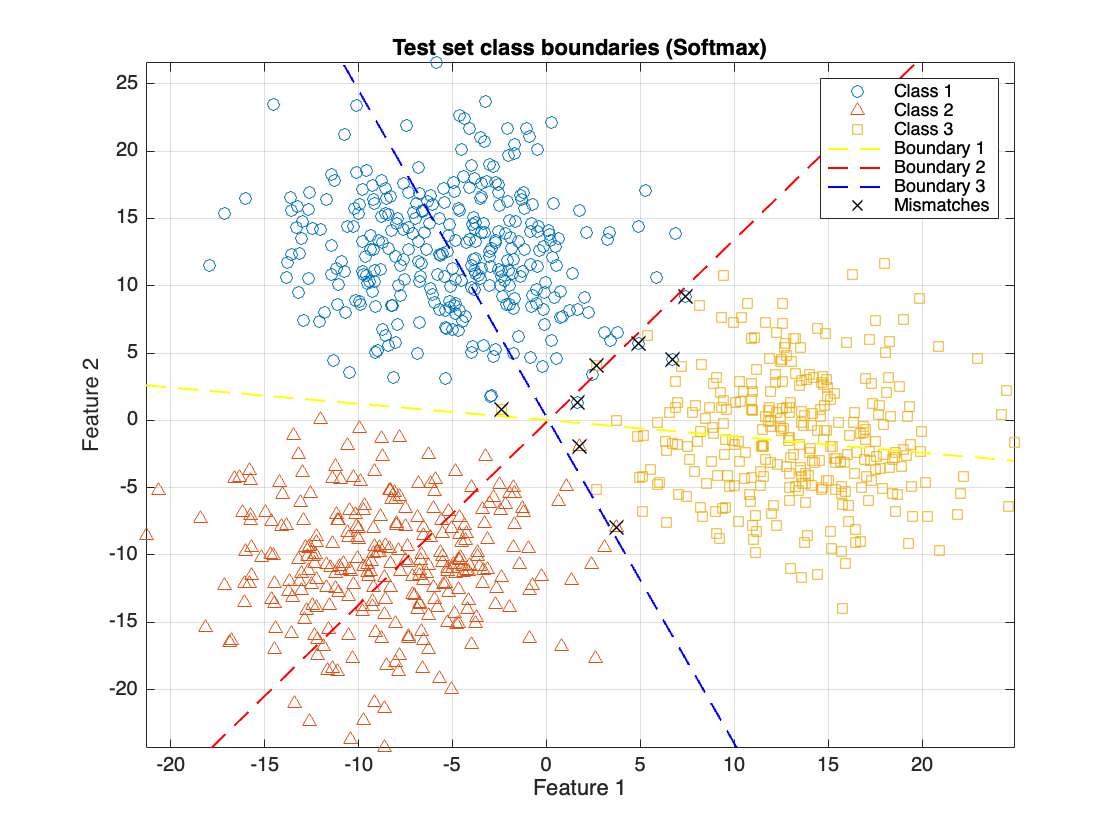

% plotting again Utest data
figure();
plot(Utest(Ytest==1,1),Utest(Ytest==1,2),"o");
xlabel("u_1");
ylabel("u_2");
hold on
grid on
plot(Utest(Ytest ==2,1),Utest(Ytest==2,2),"^");
hold on
grid on
plot(Utest(Ytest==3,1),Utest(Ytest==3,2),"s");

xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1','Class 2','Class 3');

% Defining the grid to plot the boundaries
xrange = linspace(min(Utest(:,1)), max(Utest(:,1)), 100);
yrange = linspace(min(Utest(:,2)), max(Utest(:,2)), 100);
[X1, X2] = meshgrid(xrange, yrange);

% Computing the boundaries between pairs of classes (hyperplanes)
phi_grid = [ones(numel(X1),1), X1(:), X2(:)];

% Boundary between class 1 and 2
Z12 = phi_grid * (theta_tot(:,1) - theta_tot(:,2));
Z12 = reshape(Z12, size(X1));
contour(X1, X2, Z12, [0 0], 'y--', 'LineWidth', 1, 'DisplayName', 'Boundary 1'); 

% Boundary between class 1 and 3
Z13 = phi_grid * (theta_tot(:,1) - theta_tot(:,3));
Z13 = reshape(Z13, size(X1));
contour(X1, X2, Z13, [0 0], 'r--', 'LineWidth', 1, 'DisplayName', 'Boundary 2'); 

% Boundary between class 2 and 3
Z23 = phi_grid * (theta_tot(:,2) - theta_tot(:,3));
Z23 = reshape(Z23, size(X1));
contour(X1, X2, Z23, [0 0], 'b--', 'LineWidth', 1, 'DisplayName', 'Boundary 3'); 
title('Test set class boundaries (Softmax)');

scatter(Utest(mismatches_test == 1,1), Utest(mismatches_test==1,2),80, 'k', 'x','LineWidth', 1, 'DisplayName', 'Mismatches');